wc = 2*pi*20e3

wc = 1.2566e+05

Hs = tf(wc^2,[1 wc*sqrt(2), wc^2])

Hs =
 
           1.579e10
  ---------------------------
  s^2 + 1.777e05 s + 1.579e10
 
Continuous-time transfer function.



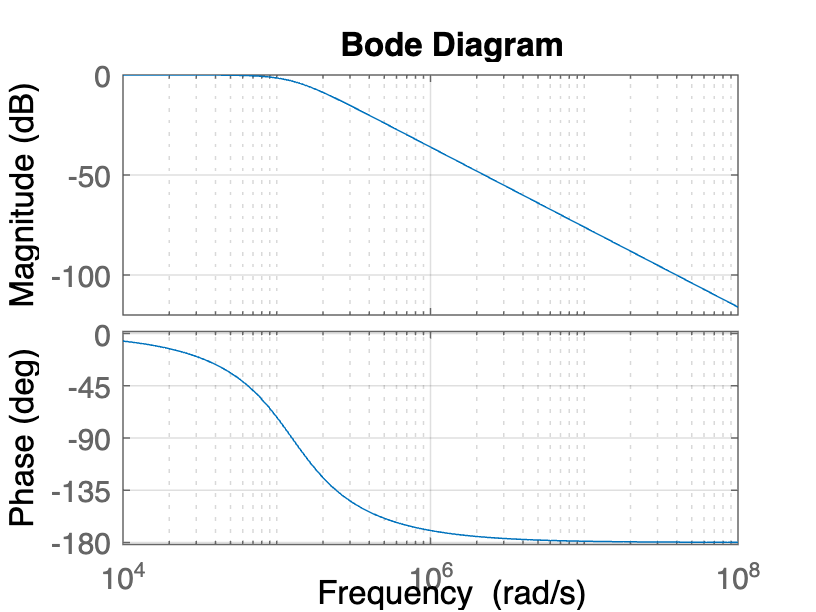

bode(Hs,{1e4,1e8})
grid

fs = 2*100*wc/(2*pi) % two decades above wc

fs = 4000000

Ts = 1/fs

Ts = 2.5000e-07

Hz = c2d(Hs, Ts)

Hz =
 
  0.0004862 z + 0.0004791
  -----------------------
  z^2 - 1.956 z + 0.9565
 
Sample time: 2.5e-07 seconds
Discrete-time transfer function.



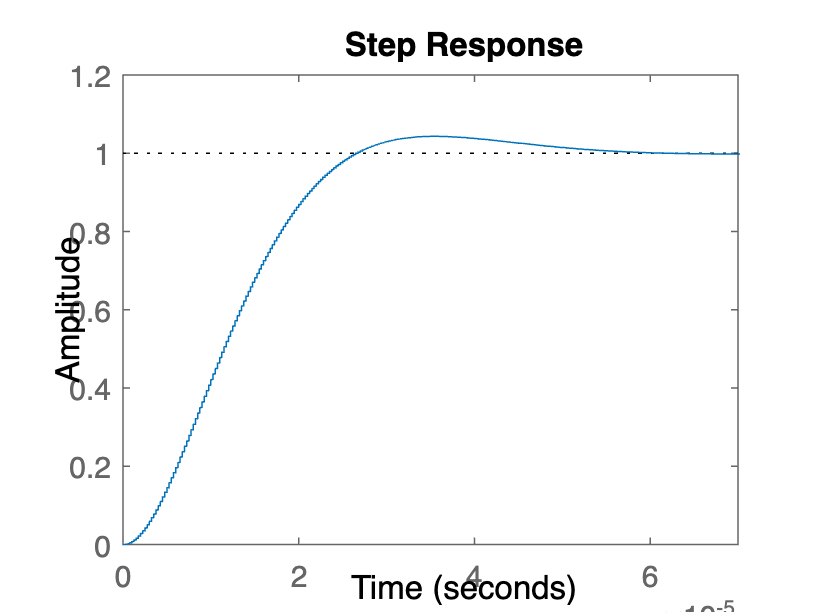

step(Hz)